# Riepilogo 05: propagazione degli errori e dell'incertezza

Questi esercizi mostrano l'applicazione dei coefficienti di sensibilità alla LPU-WCU (propagazione delle incertezze di caso peggiore), alla LPU (propagazione delle incertezze standard), e alla LPE (propagazione degli errori).

Sono ripresi i casi considerati negli esercizi sul calcolo dei coefficienti di sensibilità.

Ricordiamo che la LPU-WCU si può applicare solo nel caso di errori in ingresso indipendenti.

## 1 - Propagazione dell'incertezza nella formula del parallelo di resistenze

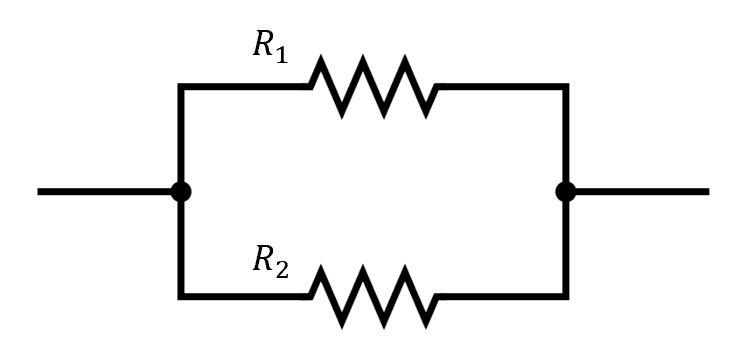

% Dati
% R1
% R2
% Ur1 = WCU relativa su R1
% Ur2 = WCU relativa su R2

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine R1, R2
% theta = resistenza parallelo
% Cr = matrice dei coefficienti di sensibilità relativi di theta
%
% Ur = vettore colonna WCU relative in ingresso
% Ur_theta = WCU relativa in uscita, supponendo errori in ingresso indipendenti
% ur_theta = SU relativa in uscita, supponendo errori in ingresso incorrelati
% ur_theta_corr = SU relativa in uscita, supponendo errori in ingresso con rho12 = -0.5

% Codice iniziale
clear
R1 = 100;
R2 = 200;
Ur1 = 1/100;
Ur2 = 2/100;

#### Soluzione

Parte vecchia

x = [R1; R2]

x =    100
   200


Rp = R1*R2/(R1+R2)

Rp = 66.6667

Cr = [R2/(R1+R2), R1/(R1+R2)]

Cr =     0.6667    0.3333


Parte nuova

Ur = [Ur1; Ur2]

Ur =     0.0100
    0.0200


Ur_theta = abs(Cr)*Ur % LPU-WCU

Ur_theta = 0.0133

ur = Ur/sqrt(3) % vettore colonna delle incertezza standard relative in ingresso

ur =     0.0058
    0.0115


Sigmar = diag(ur)^2 % matrice covarianza relativa in ingresso, errori incorrelati

Sigmar = 1.0e-03 *

    0.0333         0
         0    0.1333


Sigmar_theta = Cr*Sigmar*Cr' % LPU - matrice covarianza relativa in uscita

Sigmar_theta = 2.9630e-05

ur_theta = sqrt(diag(Sigmar_theta)) % incertezza standard relative in uscita

ur_theta = 0.0054

R = [1, -0.5; -0.5, 1] % matrice dei coefficienti di correlazione in ingresso

R =     1.0000   -0.5000
   -0.5000    1.0000


Sigmar_corr = diag(ur)*R*diag(ur) % matrice covarianza relativa in ingresso, errori correlati

Sigmar_corr = 1.0e-03 *

    0.0333   -0.0333
   -0.0333    0.1333


Sigmar_theta_corr = Cr*Sigmar_corr*Cr' % LPU - matrice covarianza relativa in uscita

Sigmar_theta_corr = 1.4815e-05

ur_theta_corr = sqrt(diag(Sigmar_theta_corr)) % incertezza standard relative in uscita

ur_theta_corr = 0.0038

## 2 - Propagazione dell'incertezza nella formula del partitore di tensione

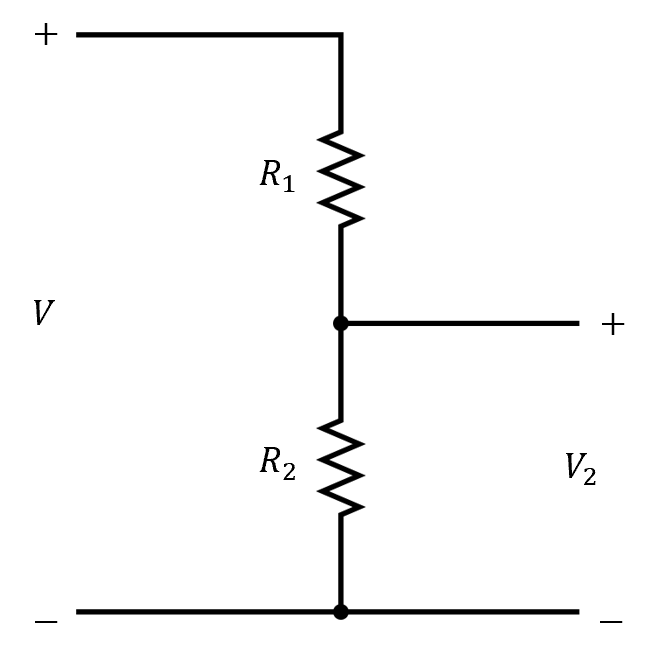

% Dati
% R1 = resistenza
% R2 = resistenza
% Ur1 = WCU relativa su R1
% Ur2 = WCU relativa su R2

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine R1, R2
% theta = V2/V, rapporto di partizione
% Cr = matrice dei coefficienti di sensibilità relativi di theta
%
% Ur = vettore colonna WCU relative in ingresso
% Ur_theta = WCU relativa in uscita, supponendo errori in ingresso indipendenti
% ur_theta = SU relativa in uscita, supponendo errori in ingresso incorrelati
% ur_theta_corr = SU relativa in uscita, supponendo errori in ingresso con rho12 = -0.5

% Codice iniziale
clear
R1 = 100;
R2 = 200;
Ur1 = 1/100;
Ur2 = 2/100;

### Soluzione

Parte vecchia

x = [R1; R2]

x =    100
   200


theta = R2/(R1+R2)

theta = 0.6667

Cr = [-R1/(R1+R2), R1/(R1+R2)]

Cr =    -0.3333    0.3333


Parte nuova

Ur = [Ur1; Ur2]

Ur =     0.0100
    0.0200


Ur_theta = abs(Cr)*Ur % LPU-WCU

Ur_theta = 0.0100

ur = Ur/sqrt(3)

ur =     0.0058
    0.0115


Sigmar = diag(ur)^2

Sigmar = 1.0e-03 *

    0.0333         0
         0    0.1333


Sigmar_theta = Cr*Sigmar*Cr'

Sigmar_theta = 1.8519e-05

ur_theta = sqrt(diag(Sigmar_theta))

ur_theta = 0.0043

R = [1, -0.5; -0.5, 1]

R =     1.0000   -0.5000
   -0.5000    1.0000


Sigmar_corr = diag(ur)*R*diag(ur)

Sigmar_corr = 1.0e-03 *

    0.0333   -0.0333
   -0.0333    0.1333


Sigmar_theta_corr = Cr*Sigmar_corr*Cr'

Sigmar_theta_corr = 2.5926e-05

ur_theta_corr = sqrt(diag(Sigmar_theta_corr))

ur_theta_corr = 0.0051

## 3 - Propagazione dell'incertezza nella misura mediante triangolazione di distanza della base e della sommità di un edificio

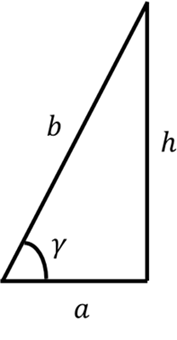

% Dati
% a = primo cateto (distanza dalla base)
% gamma = angolo in radianti
% Ur_a = WCU relativa su a
% Ur_gamma = WCU relativa su gamma

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine a, gamma
% h = secondo cateto (altezza)
% b = ipotenusa (distanza dalla sommità)
% theta = vettore colonna delle grandezze in uscita, nell'ordine h, b
% Cr = matrice dei coefficienti di sensibilità relativi di theta
%
% Ur = vettore colonna WCU relative in ingresso
% Ur_theta = vettore colonna WCU relative in uscita, supponendo errori in ingresso indipendenti
% ur_theta = vettore colonna SU relative in uscita, supponendo errori in ingresso incorrelati
%
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori sulle grandezze theta(1) e theta(2)
%
% ur_theta_corr = vettore colonna SU relative in uscita, supponendo errori in ingresso con rho12 = -0.5

% Codice iniziale
clear
a = 10;
gamma = 75*pi/180; % 75 gradi espresso in radianti
Ur_a = 1/100;
U_gamma = 0.1*pi/180;
Ur_gamma = U_gamma/gamma;

#### Soluzione

Parte vecchia

x = [a; gamma]

x =    10.0000
    1.3090


h = a*tan(gamma)

h = 37.3205

b = a/cos(gamma)

b = 38.6370

theta = [h;b]

theta =    37.3205
   38.6370


Cr = [1, gamma*(tan(gamma)^2+1)/tan(gamma); 1, gamma*tan(gamma)]

Cr =     1.0000    5.2360
    1.0000    4.8852


Parte nuova

Ur = [Ur_a; Ur_gamma] % WCU in ingresso

Ur =     0.0100
    0.0013


Ur_theta = abs(Cr)*Ur % LPU-WCU

Ur_theta =     0.0170
    0.0165


ur = Ur/sqrt(3)

ur =     0.0058
    0.0008


Sigmar = diag(ur)^2

Sigmar = 1.0e-04 *

    0.3333         0
         0    0.0059


Sigmar_theta = Cr*Sigmar*Cr'

Sigmar_theta = 1.0e-04 *

    0.4958    0.4849
    0.4849    0.4748


ur_theta = sqrt(diag(Sigmar_theta)) % SU in uscita

ur_theta =     0.0070
    0.0069


$R={\mathrm{diag}\left(u\right)}^{-1} \Sigma \;{\mathrm{diag}\left(u\right)}^{-1}$ lavorando con incertezze assolute

$R={\mathrm{diag}\left(u_r \right)}^{-1} \Sigma_r \;{\mathrm{diag}\left(u_r \right)}^{-1}$ lavorando con incertezze assolute

R_theta = diag(ur_theta)^-1*Sigmar_theta*diag(ur_theta)^-1 % formula per l'estrazione di R da Sigma

R_theta =     1.0000    0.9995
    0.9995    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.9995

R = [1, -0.5; -0.5, 1] % matrice dei coefficienti di correlazione

R =     1.0000   -0.5000
   -0.5000    1.0000


Sigmar_corr = diag(ur)*R*diag(ur)

Sigmar_corr = 1.0e-04 *

    0.3333   -0.0222
   -0.0222    0.0059


Sigmar_theta_corr = Cr*Sigmar_corr*Cr'

Sigmar_theta_corr = 1.0e-04 *

    0.2631    0.2600
    0.2600    0.2576


ur_theta_corr = sqrt(diag(Sigmar_theta_corr))

ur_theta_corr =     0.0051
    0.0051


## 4 - Propagazione dell'incertezza nel calcolo di modulo e argomento a partire da parte reale e parte immaginaria

  Questo caso si presenta, ad esempio, stimando ampiezza e fase di una sinusoide col metodo OLS.

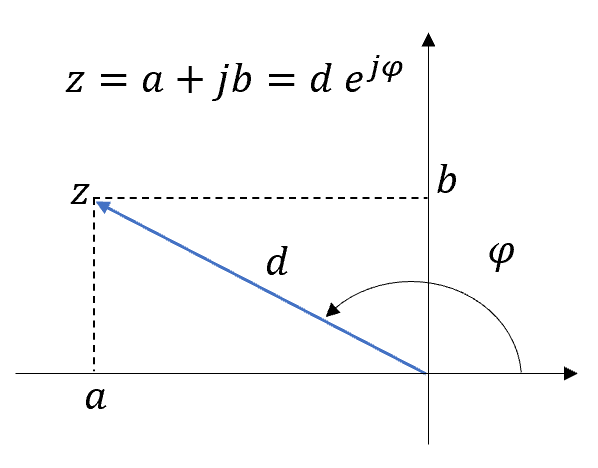

% Dati
% a = parte reale
% b = parte immaginaria
% U_a = WCU assoluta su a
% U_b = WCU assoluta su b

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine a, b
% d = modulo
% phi = argomento
% theta = vettore colonna delle grandezze in uscita, nell'ordine d, phi
% C = matrice dei coefficienti di sensibilità assoluti di theta
%
% U = vettore colonna WCU in ingresso
% U_theta = vettore colonna WCU in uscita, supponendo errori in ingresso indipendenti
% u_theta = vettore colonna SU in uscita, supponendo errori in ingresso incorrelati
%
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori sulle grandezze theta(1) e theta(2)
%
% u_theta_corr = vettore colonna SU in uscita, supponendo errori in ingresso con rho12 = -0.5

% Codice iniziale
clear
a = -10

a = -10

b = -15

b = -15

U_a = 0.01

U_a = 0.0100

U_b = 0.01

U_b = 0.0100

### Soluzione

Parte vecchia

x = [a; b] % vettore colonna grandezze in ingresso

x =    -10
   -15


d = sqrt(a^2+b^2) % modello della misurazione

d = 18.0278

phi = atan2(b,a) % modello della misurazione

phi = -2.1588

theta = [d; phi] % vettore colonna grandezze in ingresso

theta =    18.0278
   -2.1588


C = [a/d, b/d; -b/d^2, a/d^2]

C =    -0.5547   -0.8321
    0.0462   -0.0308


Parte nuova

U = [U_a; U_b] % vettore colonna WCU in ingresso

U =     0.0100
    0.0100


U_theta = abs(C)*U % LPU-WCU

U_theta =     0.0139
    0.0008


u = U/sqrt(3)

u =     0.0058
    0.0058


Sigma = diag(u)^2

Sigma = 1.0e-04 *

    0.3333         0
         0    0.3333


Sigma_theta = C*Sigma*C'

Sigma_theta = 1.0e-04 *

    0.3333   -0.0000
   -0.0000    0.0010


u_theta = sqrt(diag(Sigma_theta))

u_theta =     0.0058
    0.0003


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000   -0.0000
   -0.0000    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = -5.7263e-17

Caso in cui gli errori in ingresso hanno $\rho_{12} =-0\ldotp 5$

R = [1, -0.5; -0.5, 1]

R =     1.0000   -0.5000
   -0.5000    1.0000


Sigma_corr = diag(u)*R*diag(u)

Sigma_corr = 1.0e-04 *

    0.3333   -0.1667
   -0.1667    0.3333


Sigma_theta_corr = C*Sigma_corr*C'

Sigma_theta_corr = 1.0e-04 *

    0.1795    0.0036
    0.0036    0.0015


u_theta_corr = sqrt(diag(Sigma_theta_corr))

u_theta_corr =     0.0042
    0.0004


## 5 - Propagazione dell'incertezza nel calcolo di parte reale e parte immaginaria a partire da modulo e argomento

E' il problema inverso del precedente. In questo caso calcoliamo sia $C$ che $C_r$ (sono entrambi calcoli molto facili)

% Dati
% d = modulo
% phi = argomento
% U_d = WCU su d
% U_phi = WCU su phi

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine d, phi
% a = parte reale
% b = parte immaginaria
% theta = vettore colonna delle grandezze in uscita, nell'ordine a, b
% C = matrice dei coefficienti di sensibilità assoluti di theta
%
% U = vettore colonna WCU in ingresso
% U_theta = vettore colonna WCU in uscita, supponendo errori in ingresso indipendenti
% u_theta = vettore colonna SU in uscita, supponendo errori in ingresso incorrelati
%
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori sulle grandezze theta(1) e theta(2)
%
% u_theta_corr = vettore colonna SU in uscita, supponendo errori in ingresso con rho12 = -0.5

% Codice iniziale
clear
d = 10;
phi = 165*pi/180;
U_d = 0.01*d;
U_phi = 0.01*phi;

#### Soluzione

Parte vecchia

x = [d; phi]

x =    10.0000
    2.8798


a = d*cos(phi)

a = -9.6593

b = d*sin(phi)

b = 2.5882

theta = [a; b]

theta =    -9.6593
    2.5882


C = [cos(phi), -d*sin(phi); sin(phi), d*cos(phi)]

C =    -0.9659   -2.5882
    0.2588   -9.6593


Parte nuova

U = [U_d; U_phi] % WCU in ingresso

U =     0.1000
    0.0288


U_theta = abs(C)*U % LPU-WCU

U_theta =     0.1711
    0.3040


u = U/sqrt(3)

u =     0.0577
    0.0166


Sigma = diag(u)^2

Sigma =     0.0033         0
         0    0.0003


Sigma_theta = C*Sigma*C'

Sigma_theta =     0.0050    0.0061
    0.0061    0.0260


u_theta = sqrt(diag(Sigma_theta))

u_theta =     0.0704
    0.1613


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000    0.5349
    0.5349    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.5349

R = [1, -0.5; -0.5, 1]

R =     1.0000   -0.5000
   -0.5000    1.0000


Sigma_corr = diag(u)*R*diag(u)

Sigma_corr =     0.0033   -0.0005
   -0.0005    0.0003


Sigma_theta_corr = C*Sigma_corr*C'

Sigma_theta_corr =     0.0026    0.0019
    0.0019    0.0284


u_theta_corr = sqrt(diag(Sigma_theta_corr))

u_theta_corr =     0.0506
    0.1686


## 6 - Propagazione dell'incertezza nel calcolo del rapporto di valori picco-picco

E' un caso che si presenta spesso in pratica, anche se di solito per calcolare l'incertezza di questa misura vanno applicate le specifiche dell'oscilloscopio.

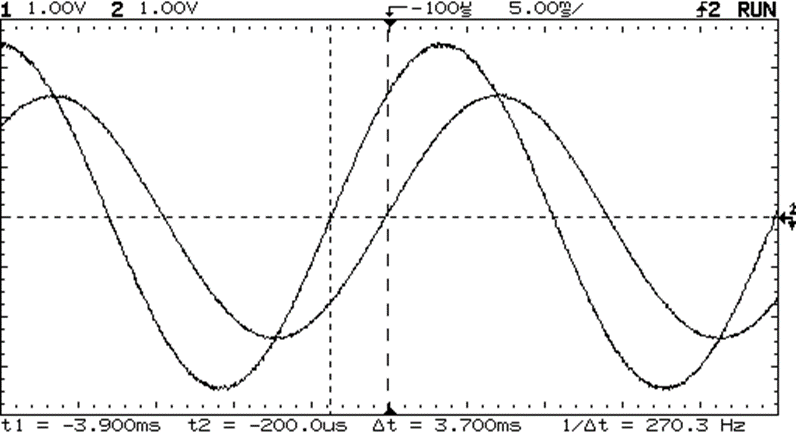

% Dati
% V1 = valore massimo tensione in uscita
% V2 = valore minimo tensione in uscita
% V3 = valore massimo tensione in ingresso
% V4 = valore minimo tensione in ingresso
% Ur1 = WCU relativa su V1
% Ur2 = WCU relativa su V1
% Ur3 = WCU relativa su V1
% Ur4 = WCU relativa su V1
% cp = probabilità di copertura

% Domande
% x = vettore colonna grandezze in ingresso, nell'ordine V1, V2, V3, V4
% H = rapporto tra valori picco-picco in uscita e in ingresso
% Cr = matrice dei coefficienti di sensibilità relativi di H
%
% Ur = vettore colonna WCU relative in ingresso
% Ur_theta = WCU relativa in uscita, supponendo errori in ingresso indipendenti
% ur_theta = SU relativa in uscita, supponendo errori in ingresso incorrelati
% ur_theta_corr = SU relativa in uscita, supponendo errori in ingresso con rho12 = -0.5
%
% kcp = fattore di copertura
% Ur_theta_cp = UE in uscita con probabilità di copertura cp

% Codice iniziale
clear
V1 = 10; V2 = -8;
V3 = 5; V4 = -3;
Ur1 = 1/100; Ur2 = 2/100;
Ur3 = 0.5/100; Ur4 = 1/100;
cp = 0.99;

#### Soluzione

Parte vecchia

x = [V1; V2; V3; V4]

x =     10
    -8
     5
    -3


Vpp_out = V1-V2

Vpp_out = 18

Vpp_in = V3-V4

Vpp_in = 8

H = Vpp_out/Vpp_in

H = 2.2500

Cr = [V1/Vpp_out, -V2/Vpp_out, -V3/Vpp_in, V4/Vpp_in]

Cr =     0.5556    0.4444   -0.6250   -0.3750


Parte nuova

Ur = [Ur1; Ur2; Ur3; Ur4] % WCU in ingresso

Ur =     0.0100
    0.0200
    0.0050
    0.0100


Ur_theta = abs(Cr)*Ur % LPU-WCU

Ur_theta = 0.0213

ur = Ur/sqrt(3) % SU relative in ingresso

ur =     0.0058
    0.0115
    0.0029
    0.0058


Sigmar = diag(ur)^2 % matrice covarianza relativa in ingresso, errori incorrelati

Sigmar = 1.0e-03 *

    0.0333         0         0         0
         0    0.1333         0         0
         0         0    0.0083         0
         0         0         0    0.0333


Sigmar_theta = Cr*Sigmar*Cr' % LPU

Sigmar_theta = 4.4568e-05

ur_theta = sqrt(diag(Sigmar_theta)) % SU relative in uscita

ur_theta = 0.0067

kcp = norminv((1+cp)/2) % fattore di copertura

kcp = 2.5758

Ur_theta_cp = kcp*ur_theta % incertezza estesa

Ur_theta_cp = 0.0172

## 7 - Propagazione degli errori per alcune funzioni monomie

% Si calcoli l'errore relativo nella misura della grandezza in uscita, ipotizzando 
% che l'errore relativo nella misura delle grandezze in ingresso sia pari a -0.5%,
% per tutte le grandezze in ingresso.

% 1) P = R*I^2
% x = [R;I]

% 2) F = G*m1*m2/d^2 
% x = [G; m1; m2; d]

% 3) R = V/I
% x = [V; I]

% 4) E = 1/2*m*v^2
% x = [m; v]

% 5) f = 1/(2*pi*sqrt(L*C))
% x = [L; C]

% 6) G = 1/R

% 7) V = 4/3*pi*r^3
% x = r

% Dati: nessuno

% er_theta1 = errore relativo in uscita, caso 1
% er_theta2 = errore relativo in uscita, caso 2
% er_theta3 = errore relativo in uscita, caso 3
% er_theta4 = errore relativo in uscita, caso 4
% er_theta5 = errore relativo in uscita, caso 5
% er_theta6 = errore relativo in uscita, caso 6
% er_theta7 = errore relativo in uscita, caso 7

% Codice iniziale
clear

### Soluzione

La LPE è:

Si consideri che l'errore relativo in ingresso è, per tutte le quantità, 

in questo caso, quindi, la LPE si calcola facilmente a mente. Tuttavia, vediamo prima la soluzione con la sua applicazione letterale.

% Applicazione letterale della LPE
er0 = -0.5/100 % errore relativo comune a tutte le grandezze in ingresso, in tutti i casi

er0 = -0.0050

Cr1 = [1, 2]; % matrice dei coefficienti relativi di sensibilità (vettore riga)
er1 = [er0; er0]; % vettore colonna degli errori relativi in ingresso, caso 1
er_theta1 = Cr1*er1 % LPE

er_theta1 = -0.0150

Cr2 = [1, 1, 1, -2];
er2 = [er0; er0; er0; er0]; % vettore colonna degli errori relativi in ingresso, caso 2
er_theta2 = Cr2*er2 % LPE

er_theta2 = -0.0050

Cr3 = [1, -1]; % matrice dei coefficienti relativi di sensibilità (vettore riga)
er3 = [er0; er0]; % vettore colonna degli errori relativi in ingresso, caso 3
er_theta3 = Cr3*er3 % LPE

er_theta3 = 0

Cr4 = [1, 2]; % matrice dei coefficienti relativi di sensibilità (vettore riga)
er4 = [er0; er0]; % vettore colonna degli errori relativi in ingresso, caso 4
er_theta4 = Cr4*er4 % LPE

er_theta4 = -0.0150

Cr5 = [-1/2, -1/2]; % matrice dei coefficienti relativi di sensibilità (vettore riga)
er5 = [er0; er0]; % vettore colonna degli errori relativi in ingresso, caso 5
er_theta5 = Cr5*er5 % LPE

er_theta5 = 0.0050

Cr6 = -1; % matrice dei coefficienti relativi di sensibilità (in questo caso è uno scalare)
er6 = er0; % vettore colonna degli errori relativi in ingresso, caso 6
er_theta6 = Cr6*er6 % LPE

er_theta6 = 0.0050

Cr7 = 3; % matrice dei coefficienti relativi di sensibilità (in questo caso è uno scalare)
er7 = er0; % vettore colonna degli errori relativi in ingresso, caso 7
er_theta7 = Cr7*er7 % LPE

er_theta7 = -0.0150

In realtà, il calcolo si esegue facilmente a mente, facendo la somma dei prodotti dei coefficienti di sensibilità per l'errore relativo pari a -0.5%, uguale naturalmente alla somma dei coefficienti di sensibilità moltiplicata per l'errore relativo

% Alternativa
er_theta1 = -1.5/100 % Cr1 = [1, 2]
er_theta2 = -0.5/100 % Cr2 = [1, 1, 1, -2]
er_theta3 = 0 % Cr3 = [1, -1]
er_theta4 = -1.5/100 % Cr4 = [1, 2]
er_theta5 = 0.5/100 % Cr5 = [-1/2, -1/2]
er_theta6 = 0.5/100 % Cr6 = -1
er_theta7 = -1.5/100 % Cr7 = 3

Equivalentemente, si può calcolare moltiplicare la somma degli elementi di C (fatta a mente o con operazione Matlab) per l'errore relativo comune a tutte le grandezze di ingresso.

% Alternativa
er0 = -0.5/100 % errore relativo comune alle grandezze in ingresso

er0 = -0.0050


er_theta1 = 3*er0 % 3 è la somma degli elementi di Cr, sum(Cr) con Cr1 = [1, 2]

er_theta1 = -0.0150

er_theta2 = 1*er0 

er_theta2 = -0.0050

er_theta3 = 0*er0 

er_theta3 = 0

er_theta4 = 3*er0 

er_theta4 = -0.0150

er_theta5 = -1*er0

er_theta5 = 0.0050

er_theta6 = -1*er0

er_theta6 = 0.0050

er_theta7 = 3*er0

er_theta7 = -0.0150


% Si noti che, se Cr è una matrice, occorre eseguire sum(Cr,2),
% perché la somma deve essere lungo le righe